%% Step 1: Diagnostic clustering (HDBSCAN) on PCA space
% Purpose: Detect whether density-separated structure exists (may return 1 cluster).

clear; clc;

% ---- User edit (minimum) ----
cfg = struct();
cfg.repoRoot   = pwd;                 % repo root (edit if needed)
cfg.demo03RunDir = "";                % if known, set full path; else leave "" to auto-find
cfg.runDir     = local_make_run_dir(fullfile(cfg.repoRoot, "data_processed"), "demo05");

% HDBSCAN dependency policy:
%   "prefer_addon"  : use Add-On if available, else try vendored third_party/hdbscan
%   "prefer_vendor" : try vendored first, else Add-On
%   "addon_only"    : never touch vendored
%   "vendor_only"   : require vendored
cfg.demo05 = struct();
cfg.demo05.hdbscanPolicy   = "prefer_addon";
cfg.demo05.minClusterSize  = 20;
cfg.demo05.minSamples      = [];     % optional (minpts). keep [] for implementation default

% ---- Load demo03 state (E/meta/Zpca/U2) ----
S = local_load_demo03_state(cfg);
meta = S.meta;
E    = S.E;

% Ensure PCA/UMAP exist (compute if missing)
if isfield(S,"Zpca") && ~isempty(S.Zpca)
    Zpca = S.Zpca;
else
    fprintf("Zpca not found in demo03 state. Computing PCA...\n");
    pcaDims = 50;
    if isfield(S,"pcaDims") && ~isempty(S.pcaDims), pcaDims = double(S.pcaDims); end
    Zpca = local_compute_pca(E, pcaDims);
end

Zpca not found in demo03 state. Computing PCA...



if isfield(S,"U2") && ~isempty(S.U2)
    U2 = S.U2;
else
    fprintf("U2 not found in demo03 state. Computing UMAP (2D)...\n");
    U2 = local_compute_umap(Zpca);
end

N = size(Zpca,1);
fprintf("Loaded: N=%d works, PCA dims=%d\n", N, size(Zpca,2));

Loaded: N=1000 works, PCA dims=50



% ---- Run HDBSCAN (diagnostic) ----
minClusterSize = cfg.demo05.minClusterSize;
minSamples     = cfg.demo05.minSamples;
policy         = cfg.demo05.hdbscanPolicy;

fprintf("Running HDBSCAN on PCA space... (mcs=%d)\n", minClusterSize);

Running HDBSCAN on PCA space... (mcs=20)


[hdb_label, hdb_prob] = local_call_hdbscan(cfg, Zpca, minClusterSize, minSamples, N, policy);

Training cluster hierarchy...
	Data matrix size:
		1000 points x 50 dimensions

	Min # neighbors: 5
	Min cluster size: 20
	Min # of clusters: 1
	Skipping every 0 iteration

Training took 0.118 seconds



hdb_label = hdb_label(:);
if isempty(hdb_prob), hdb_prob = nan(N,1); else, hdb_prob = hdb_prob(:); end

nNoise = sum(hdb_label<=0);
clusters = unique(hdb_label(hdb_label>0));
fprintf("HDBSCAN result: clusters=%d | noise=%d (%.1f%%)\n", numel(clusters), nNoise, 100*nNoise/N);

HDBSCAN result: clusters=1 | noise=719 (71.9%)



% Save HDBSCAN assignment
T_hdb = table( ...
    string(meta.work_id(:)), double(meta.year(:)), hdb_label, hdb_prob, U2(:,1), U2(:,2), ...
    'VariableNames', {'work_id','year','hdbscan_cluster','hdbscan_probability','x','y'});
outHdbCsv = fullfile(cfg.runDir, "demo05_hdbscan.csv");
writetable(T_hdb, outHdbCsv);
fprintf("Wrote: %s\n", outHdbCsv);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\20251223_172418_demo05\demo05_hdbscan.csv



save(fullfile(cfg.runDir, "demo05_step1_state.mat"), ...
    "Zpca","U2","hdb_label","hdb_prob","minClusterSize","minSamples","policy","-v7.3");

%% Step 2: Constructive clustering (k-means) + simple k sweep
% Purpose: Provide a user-controlled summarization even if HDBSCAN returns 1 cluster.
% We DO NOT claim an "optimal" K; we only report a diagnostic.

cfg.demo05.kSweep = 4:12;
cfg.demo05.kmeansReplicates = 5;
cfg.demo05.kmeansMaxIter    = 300;

kList = cfg.demo05.kSweep;
sil = nan(numel(kList),1);
idxAll = cell(numel(kList),1);

% k-means on PCA space (recommended). Use cosine distance for embeddings-like behavior.
fprintf("Running k-means sweep on PCA space...\n");

Running k-means sweep on PCA space...


for i = 1:numel(kList)
    K = kList(i);
    fprintf("  K=%d ... ", K);

    % Use kmeans with cosine distance if available. Otherwise fall back to sqeuclidean.
    try
        idx = kmeans(Zpca, K, ...
            'Distance', 'cosine', ...
            'Replicates', cfg.demo05.kmeansReplicates, ...
            'MaxIter', cfg.demo05.kmeansMaxIter, ...
            'Display', 'off');
    catch
        idx = kmeans(Zpca, K, ...
            'Replicates', cfg.demo05.kmeansReplicates, ...
            'MaxIter', cfg.demo05.kmeansMaxIter, ...
            'Display', 'off');
    end

    % silhouette can be expensive; on 1k–10k it's ok, but for big N you may subsample.
    try
        s = silhouette(Zpca, idx, 'cosine');
    catch
        s = silhouette(Zpca, idx);
    end
    sil(i) = mean(s, 'omitnan');
    idxAll{i} = idx(:);

    fprintf("silhouette=%.3f\n", sil(i));
end

  K=4 ... 

silhouette=0.135


  K=5 ... 

silhouette=0.136


  K=6 ... 

silhouette=0.135


  K=7 ... 

silhouette=0.127


  K=8 ... 

silhouette=0.133


  K=9 ... 

silhouette=0.149


  K=10 ... 

silhouette=0.132


  K=11 ... 

silhouette=0.137


  K=12 ... 

silhouette=0.138



% pick "best" by max mean silhouette (only as a convenience)
[~, bestI] = max(sil);
Kbest = kList(bestI);
idxK  = idxAll{bestI};

T_kdiag = table(kList(:), sil(:), 'VariableNames', {'K','mean_silhouette'});
outKdiag = fullfile(cfg.runDir, "demo05_kmeans_silhouette.csv");
writetable(T_kdiag, outKdiag);
fprintf("Wrote: %s\n", outKdiag);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\20251223_172418_demo05\demo05_kmeans_silhouette.csv


fprintf("Selected Kbest=%d (max mean silhouette=%.3f) [diagnostic only]\n", Kbest, sil(bestI));

Selected Kbest=9 (max mean silhouette=0.149) [diagnostic only]



% Save chosen k-means assignment
T_km = table( ...
    string(meta.work_id(:)), double(meta.year(:)), idxK, U2(:,1), U2(:,2), ...
    'VariableNames', {'work_id','year','kmeans_cluster','x','y'});
outKmCsv = fullfile(cfg.runDir, sprintf("demo05_kmeans_K%d.csv", Kbest));
writetable(T_km, outKmCsv);
fprintf("Wrote: %s\n", outKmCsv);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\20251223_172418_demo05\demo05_kmeans_K9.csv


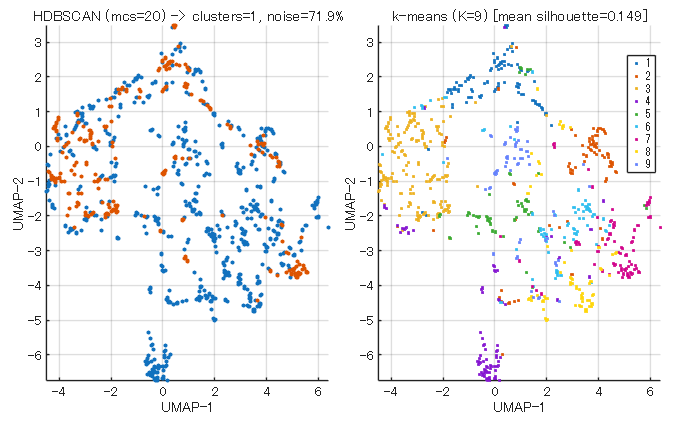


save(fullfile(cfg.runDir, "demo05_step2_state.mat"), ...
    "kList","sil","Kbest","idxK","-v7.3");

%% Step 3: Parallel visualization (same UMAP space)
% Left: HDBSCAN (single color for cluster + gray for noise if any)
% Right: k-means (colored by cluster)

f = figure("Name","demo_05 Parallel view: HDBSCAN vs k-means", "Color","w");
tiledlayout(1,2, "Padding","compact", "TileSpacing","compact");

% --- HDBSCAN view ---
nexttile;
isNoise = (hdb_label<=0);
if any(isNoise)
    scatter(U2(isNoise,1), U2(isNoise,2), 6, 'filled'); hold on;
    scatter(U2(~isNoise,1), U2(~isNoise,2), 6, 'filled');
else
    scatter(U2(:,1), U2(:,2), 6, 'filled');
end
axis tight; grid on;
title(sprintf("HDBSCAN (mcs=%d) -> clusters=%d, noise=%.1f%%", ...
    minClusterSize, numel(clusters), 100*sum(isNoise)/N));
xlabel("UMAP-1"); ylabel("UMAP-2");

% --- k-means view ---
nexttile;
gscatter(U2(:,1), U2(:,2), idxK);
axis tight; grid on;
title(sprintf("k-means (K=%d) [mean silhouette=%.3f]", Kbest, sil(bestI)));
xlabel("UMAP-1"); ylabel("UMAP-2");

% Export figure
outFig = fullfile(cfg.runDir, sprintf("demo05_parallel_hdbscan_vs_kmeans_K%d.png", Kbest));
exportgraphics(f, outFig, "Resolution", 300);

fprintf("Wrote: %s\n", outFig);

Wrote: D:\workspace\github\openalex-topic-map\data_processed\20251223_172418_demo05\demo05_parallel_hdbscan_vs_kmeans_K9.png



%% ---- Local helpers ----
function runDir = local_make_run_dir(baseDir, tag)
if ~isfolder(baseDir), mkdir(baseDir); end
stamp = datestr(now, "yyyymmdd_HHMMSS");
runDir = fullfile(baseDir, stamp + "_" + string(tag));
mkdir(runDir);
end

function S = local_load_demo03_state(cfg)
% demo05 MUST NOT regenerate embeddings.
% It reuses demo03 outputs under runs/** (same policy as demo04).

demo03RunDir = "";
if isfield(cfg,"demo03RunDir") && strlength(string(cfg.demo03RunDir))>0
    demo03RunDir = string(cfg.demo03RunDir);
end
if isfield(cfg,"input") && isfield(cfg.input,"demo03RunDir") && strlength(string(cfg.input.demo03RunDir))>0
    demo03RunDir = string(cfg.input.demo03RunDir);
end

if strlength(demo03RunDir)==0
    runsRoot = fullfile(cfg.repoRoot, "runs");
    assert(isfolder(runsRoot), "runs/ folder not found: %s", runsRoot);
    d = dir(fullfile(runsRoot, "**", "demo03_embeddings.mat"));
    assert(~isempty(d), "No demo03_embeddings.mat found under runs/. Run demo03 first.");
    [~, idxNewest] = max([d.datenum]);
    demo03RunDir = string(d(idxNewest).folder);
end

embMat = fullfile(demo03RunDir, "demo03_embeddings.mat");
assert(isfile(embMat), "Missing demo03 embeddings: %s", embMat);

tmp = load(embMat, "E", "meta");
assert(isfield(tmp,"E") && isfield(tmp,"meta"), "demo03_embeddings.mat must contain E and meta.");

S = struct();
S.E = tmp.E;
S.meta = tmp.meta;
S.demo03RunDir = demo03RunDir;

% Optional reuse: UMAP coordinates from demo03_umap2d.csv
S.U2 = [];
u2Csv = fullfile(demo03RunDir, "demo03_umap2d.csv");
if isfile(u2Csv)
    T = readtable(u2Csv);
    if all(ismember(["work_id","x","y"], string(T.Properties.VariableNames)))
        key = string(S.meta.work_id(:));
        [tf, loc] = ismember(key, string(T.work_id));
        if all(tf)
            S.U2 = [T.x(loc), T.y(loc)];
        end
    end
end

% Keep empty for recompute in demo05 if needed
S.Zpca = [];
end

function Zpca = local_compute_pca(E, pcaDims)
E = single(E);
E = double(E); % PCA expects double in many cases
% zscore by features
E = zscore(E, 0, 1);
[coeff, score] = pca(E, "NumComponents", pcaDims);
Zpca = score(:,1:pcaDims);
end

function U2 = local_compute_umap(Zpca)
% Uses Statistics and Machine Learning Toolbox (R2025b)
% If 'umap' function exists (File Exchange), you can swap this.
try
    U2 = umap(Zpca);
catch
    % fallback: t-SNE (slower)
    warning("umap() not available. Falling back to tsne().");
    U2 = tsne(Zpca);
end
end

function [lab, prob] = local_call_hdbscan(cfg, X, minClusterSize, minSamples, N, policy)
lab  = [];
prob = [];

policy = string(policy);
local_ensure_hdbscan_on_path(cfg, policy);

% function API
if exist("hdbscan","file") ~= 0
    try
        if isempty(minSamples)
            out = hdbscan(X, minClusterSize);
        else
            out = hdbscan(X, minClusterSize, "MinSamples", minSamples);
        end
        if isstruct(out)
            if isfield(out,"labels"), lab = out.labels; end
            if isfield(out,"probabilities"), prob = out.probabilities; end
        elseif istable(out)
            if ismember("labels", out.Properties.VariableNames), lab = out.labels; end
            if ismember("probabilities", out.Properties.VariableNames), prob = out.probabilities; end
        elseif isnumeric(out)
            lab = out;
        end
    catch
        lab = [];
    end
end

% class API (Jorsorokin-HDBSCAN style)
if isempty(lab) && exist("HDBSCAN","file") ~= 0
    try
        c = HDBSCAN(X);
        if ~isempty(minSamples)
            c.minpts = double(minSamples);
        end
        c.minclustsize = double(minClusterSize);
        c.run_hdbscan();
        if isprop(c,"labels"), lab = c.labels; end
        if isprop(c,"P"),      prob = c.P; end
    catch
        lab = [];
    end
end

if isempty(lab)
    w1 = string(which("hdbscan","-all"));
    w2 = string(which("HDBSCAN","-all"));
    msg = strjoin([ ...
        "HDBSCAN implementation not found / not callable.", newline, ...
        "Expected entry points: hdbscan(...) or HDBSCAN class.", newline, ...
        "Policy: " + policy, newline, ...
        newline, ...
        "which hdbscan -all:", newline, "  " + strjoin(w1, newline + "  "), newline, ...
        "which HDBSCAN -all:", newline, "  " + strjoin(w2, newline + "  "), newline ...
    ], "");
    error("%s", msg);
end

lab = lab(:);
if nargin >= 5 && ~isempty(N)
    if isempty(prob), prob = nan(N,1); else, prob = prob(:); end
end
end

function local_ensure_hdbscan_on_path(cfg, policy)
policy = string(policy);
hasAny = (exist("hdbscan","file") ~= 0) || (exist("HDBSCAN","file") ~= 0);

if policy == "addon_only"
    return;
end
if policy == "prefer_addon" && hasAny
    return;
end

% vendored minimal addpath (NO genpath)
vendorRoot = fullfile(cfg.repoRoot, "third_party", "hdbscan");
if ~isfolder(vendorRoot)
    if policy == "vendor_only"
        error("policy=vendor_only but vendored folder missing: %s", vendorRoot);
    end
    return;
end

d = dir(fullfile(vendorRoot, "**", "HDBSCAN.m"));
if isempty(d)
    if policy == "vendor_only"
        error("policy=vendor_only but HDBSCAN.m not found under: %s", vendorRoot);
    end
    return;
end

hdbDir = string(d(1).folder);
addpath(hdbDir);

% add common dependency subfolders (still no genpath)
sub = ["source","src","utils","lib","code"];
for k = 1:numel(sub)
    p = fullfile(hdbDir, sub(k));
    if isfolder(p), addpath(p); end
end

rehash toolboxcache;
fprintf("Added HDBSCAN path(s): %s\n", hdbDir);
end
